%% Simplex example page 16 [lay] MAXIMIZATION

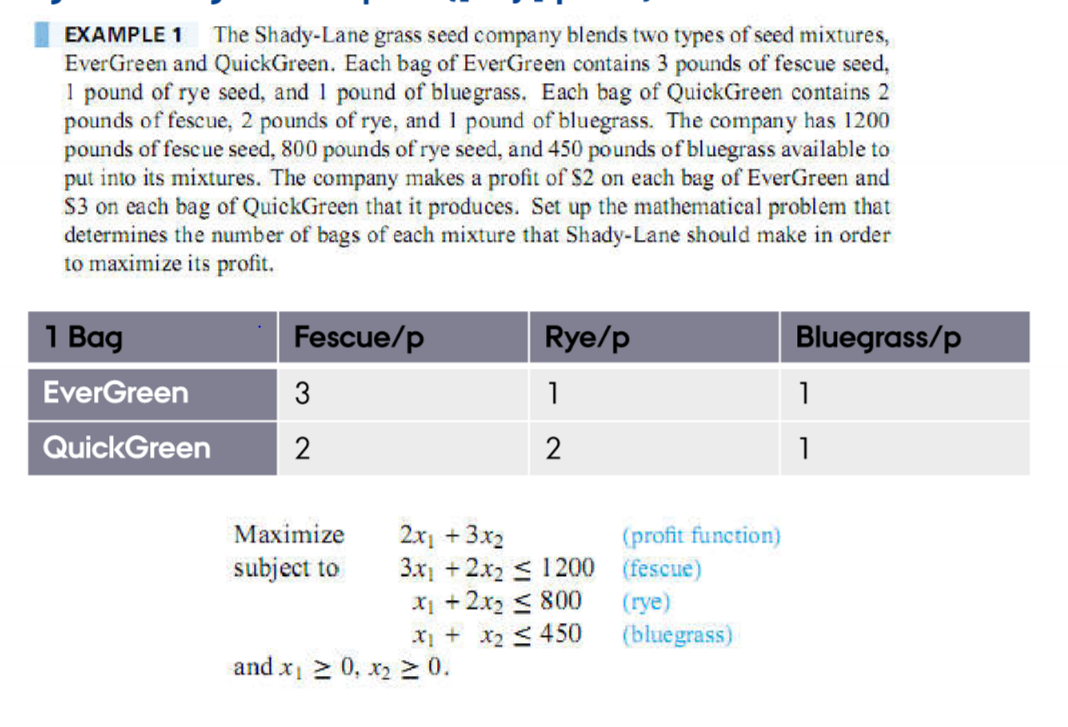

%% Given variables
%A is constraints matrix and slack variables addes to each of the
%constraints (left side of constraints) also add z (zeroes)
A=[3 2 1 0 0 0; 
   1 2 0 1 0 0;
   1 1 0 0 1 0];

% Right side of the constraints
b=[1200;
   800;
   450];

%Constatns of the objective functions and added slack variables and z which
%is -1
c=-[2;3;0;0;0;-1];

% Positions of slack varibles
v=[3;4;5];

%Run calculations
simplex(c,A,b,v,1)

 
Initial tableau:
  Columns 1 through 4

       3              2              1              0       
       1              2              0              1       
       1              1              0              0       
      -2             -3              0              0       

  Columns 5 through 7

       0              0           1200       
       0              0            800       
       1              0            450       
       0              1              0       

Pivot point:
       2              2       

New tableau:
  Columns 1 through 4

       2              0              1             -1       
       1/2            1              0              1/2     
       1/2            0              0             -1/2     
      -1/2            0              0              3/2     

  Columns 5 through 7

       0              0            400       
       0              0            400       
       1              0             50       
       0          

ans =      100       
     350       
     200       
       0       
       0       
       0       


% In results: you can se x1, x2 .... xn in last answer outpout. And total profit (maximized) can be seen in last table as corner value

Example how to create dual problem:

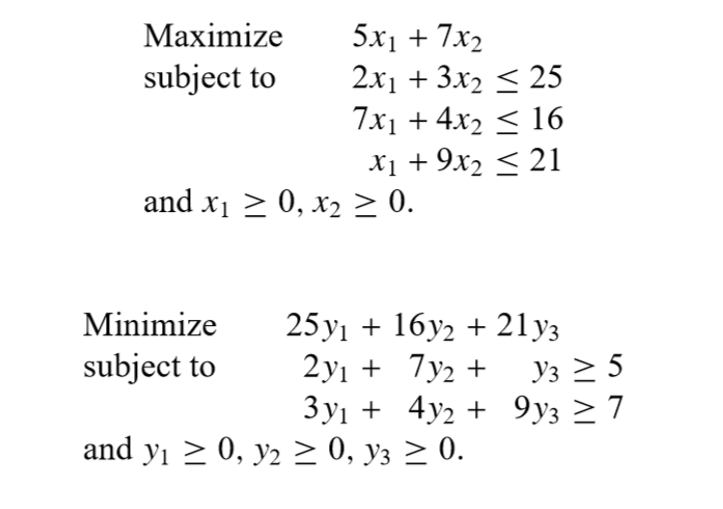

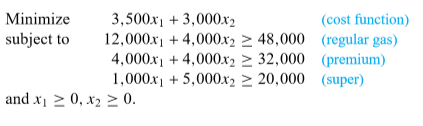

% MINIMIZATION

%create dual problem and maximize using simplex, solution is in slack
%variables

% Make dual:


A = [12000 4000 1 0 0 0;
     4000 4000 0 1 0 0;
     1000 5000 0 0 1 0];
 
b = [48000;32000;20000];

c = -[3500; 3000; 0; 0; 0 ;-1];
 
v=[3;4;5];
simplex(c,A,b,v,1)

 
Initial tableau:
  Columns 1 through 4

   12000           4000              1              0       
    4000           4000              0              1       
    1000           5000              0              0       
   -3500          -3000              0              0       

  Columns 5 through 7

       0              0          48000       
       0              0          32000       
       1              0          20000       
       0              1              0       

Pivot point:
       1              1       

New tableau:
  Columns 1 through 4

       1              1/3            1/12000        0       
       0           8000/3           -1/3            1       
       0          14000/3           -1/12           0       
       0          -5500/3            7/24           0       

  Columns 5 through 7

       0              0              4       
       0              0          16000       
       1              0          16000       
       0          

ans =       20/7     
      24/7     
       0       
   48000/7     
       0       
       0       
